Cleaning workspace

clear;
clc;

Loading data:

if isfile('data.mat')
     load('data.mat');
end

# Problem:

T_0 = 0;  % Time begin
T_1 = 2; % Time end

a = 0; % x left boundary
b = 1; % x right boundary

syms x;
syms t;

u_a = 0; % Temperature at left boundary
u_b = 0; % Temperature at right boundary

u_0 = sin(x * (x + 1) * pi/2); % Temperature at t = T_0

D = 0.2; % L[u(x, t)] = D * d^2u/dx^2; D = lambda / (rho * c)

N = 10; % Amount of points in [a; b] segment
M = 500; % Amount of points in [0; T] segment

# Explicit method:

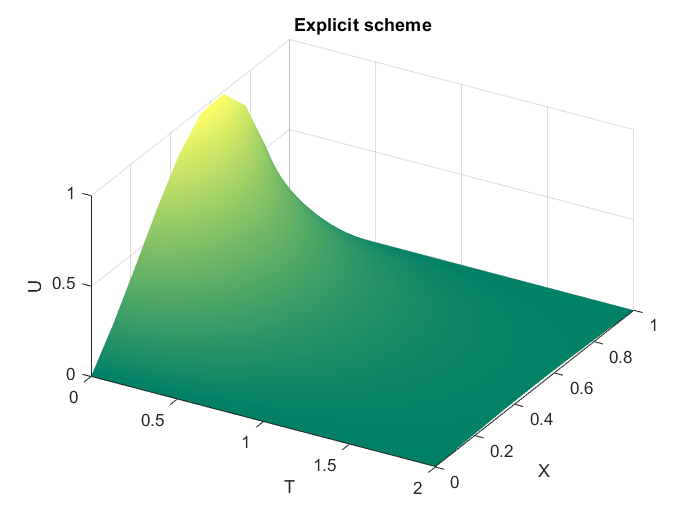

tableExp = ExplicitMethod(T_0, T_1, a, b, u_a, u_b, u_0, N, M, D);
display_solution(tableExp, 'Explicit scheme', T_0, T_1, a, b);

# Implicit method:

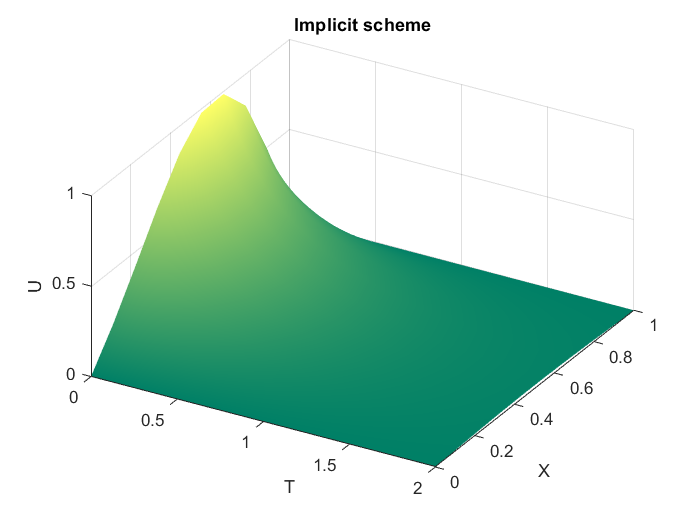

tableImp = ImplicitMethod(T_0, T_1, a, b, u_a, u_b, u_0, N, M, D);
display_solution(tableImp, 'Implicit scheme', T_0, T_1, a, b);

Saving data:

save('data.mat');

#### Functions:

function display_solution(table, name, T_0, T_1, a, b)
    figure;
    x = linspace(a, b, size(table, 1));
    t = linspace(T_0, T_1, size(table, 2));
    surf(t, x, table);
    title(name);
    xlabel('T');
    ylabel('X');
    zlabel('U');
    colormap summer;
    shading interp;
    view([30 45]);
end